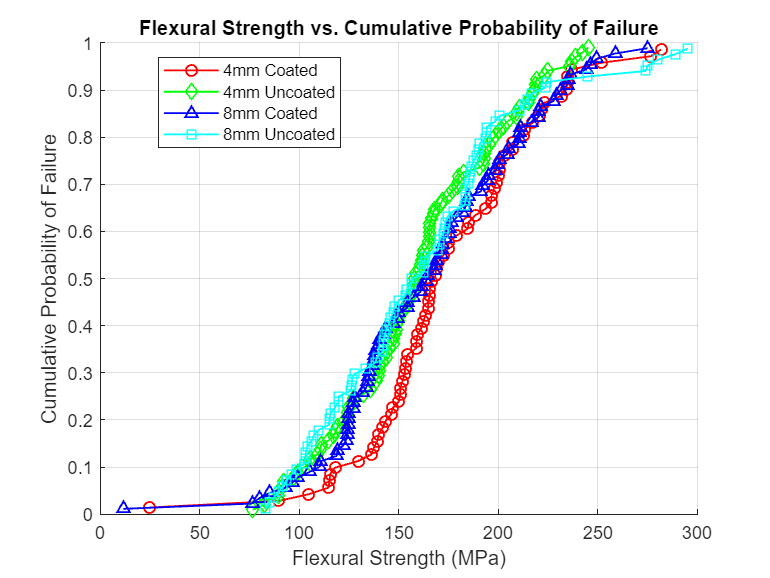

% This algorithm plots Flexural Strength vs Probability of Failure 
% using data obtained during a 3-Point Bending Test on 
% glass rods of varying diameters
% ATTRIBUTION: algorithm was written by myself, with the help of
% ChatGPT to determine how to filter and sort data values for plotting
% Mathworks.com for MATLAB syntax

file = '/Users/vinay/Downloads/Lab-9_All_Sections.csv';
data = readtable(file,'HeaderLines',3);

p = pi;
number = data{1:403, 2};
label = data{1:403,3};
diameter = data{1:403,4};
radius = diameter./2;
support_span = data{1:403,5};
max_force = data{1:403,6};
flex_strength = (max_force.*support_span)./(p.*((radius).^3));

% Add flex_strength to the data table
data.flex_strength(1:403) = flex_strength;

% Filter out any erroneous data, as earlier plotting indicated that there
% was lots of data with stress values that are much too high
data = data(data.flex_strength <= 300, :);

% Group diameters between 3 and 5
fourmm_indices = diameter >= 3 & diameter <= 5;
fourmm_data = data(fourmm_indices, :);

% Group diameters between 7 and 9
eightmm_indices = diameter >= 7 & diameter <= 9;
eightmm_data = data(eightmm_indices, :);

% Split the 4mm group into 'coated' and 'uncoated'
fourmm_coated_indices = contains(fourmm_data{:,3}, 'coated')  & ~contains(fourmm_data{:,3}, 'uncoated');
fourmm_coated_data = fourmm_data(fourmm_coated_indices, :);

fourmm_uncoated_indices = contains(fourmm_data{:,3}, 'uncoated');
fourmm_uncoated_data = fourmm_data(fourmm_uncoated_indices, :);

% Split the 8mm group into 'coated' and 'uncoated'
eightmm_coated_indices = contains(eightmm_data{:,3}, 'coated') & ~contains(eightmm_data{:,3}, 'uncoated');
eightmm_coated_data = eightmm_data(eightmm_coated_indices, :);

eightmm_uncoated_indices = contains(eightmm_data{:,3}, 'uncoated');
eightmm_uncoated_data = eightmm_data(eightmm_uncoated_indices, :);

% Sorting the data by flexural strength in ascending order for each group
fourmm_coated_sorted = sort(fourmm_coated_data.flex_strength);
fourmm_uncoated_sorted = sort(fourmm_uncoated_data.flex_strength);
eightmm_coated_sorted = sort(eightmm_coated_data.flex_strength);
eightmm_uncoated_sorted = sort(eightmm_uncoated_data.flex_strength);

% Calculating the cumulative probability of failure for each group
N_coated_4mm = length(fourmm_coated_sorted);
N_uncoated_4mm = length(fourmm_uncoated_sorted);
N_coated_8mm = length(eightmm_coated_sorted);
N_uncoated_8mm = length(eightmm_uncoated_sorted);

P_coated_4mm = (1:N_coated_4mm)' / (N_coated_4mm + 1);
P_uncoated_4mm = (1:N_uncoated_4mm)' / (N_uncoated_4mm + 1);
P_coated_8mm = (1:N_coated_8mm)' / (N_coated_8mm + 1);
P_uncoated_8mm = (1:N_uncoated_8mm)' / (N_uncoated_8mm + 1);

% Creating the cumulative probability plot
figure;
hold on;

plot(fourmm_coated_sorted, P_coated_4mm, 'r', 'LineWidth', 1,'Marker','o');
plot(fourmm_uncoated_sorted, P_uncoated_4mm, 'g', 'LineWidth', 1,'Marker','d');
plot(eightmm_coated_sorted, P_coated_8mm, 'b', 'LineWidth', 1,'Marker','^');
plot(eightmm_uncoated_sorted, P_uncoated_8mm, 'c', 'LineWidth', 1,'Marker','s');

% Customize the plot
title('Flexural Strength vs. Cumulative Probability of Failure');
xlabel('Flexural Strength (MPa)');
ylabel('Cumulative Probability of Failure');
legend('4mm Coated', '4mm Uncoated', '8mm Coated', '8mm Uncoated', 'Location', 'best');
grid on;
hold off;